# Practical hologram simulation

Achieved:

- PSF calculation from OTF

- View scope constraint

- NA constraint

- Different sampling in the object space and hologram space

- Optimization reconstructuion with ADMM

Made by [Congli Wang](https://congliwang.github.io/) and [Ni Chen](https://ni-chen.github.io/) on Feb. 14, 2020.

## System parameters

close all; clear; clc;

rng('default'); % fixed seed for reproducibility
addpath(genpath('./function/'));  % Add funtion path with sub-folders

out_dir = '../lab-notebook/img/'

out_dir = '../lab-notebook/img/'


% Parameters of the hologram system
sys.lambda = 632.8e-9;   % illumination wavelength
sys.NA     = 0.4;        % sys.NA of the objective lens
sys.M      = 10;          % Magnification of the objective lens
sys.pps    = 3.45e-6;  % pixel pitch of CCD camera
sys.z0     = 15e-3;      % distance between the hologram and the center plane of the 3D object
sys.Ns     = 2048;     % pixel number of the camera sensor
sys.Lin    = 21e-3/10;      % sys.NA*2*8.162e-3;
    
sys.Ns_bound = round((sys.Lin*sys.M - sys.Ns*sys.pps)/(2*sys.pps))        % boundary crop of the sensor

sys = struct with fields:
      lambda: 6.3280e-07
          NA: 0.4000
           M: 10
         pps: 3.4500e-06
          z0: 0.0150
          Ns: 2048
         Lin: 0.0021
    Ns_bound: 2019



% parameters of the object
obj.Nz      = 1;         % axial size
obj.ppo     = 1e-9;    % pixel pitch of the object, sys.pps/20
obj.dz      = 5000e-6;     % depth interval of the object slices


% obj.Nxy     = round(sys.Ns*M) + sys.Ns_bound*2   %lateral size (must be an odd number!)
obj.Nxy     = round(sys.Lin/obj.ppo)    %lateral size (must be an odd number!)

obj = struct with fields:
     Nz: 1
    ppo: 2.5000e-06
     dz: 0.0050
    Nxy: 840


% obj.Nxy     = round((sys.Ns)*M)    %lateral size (must be an odd number!)
% Nxy_bound   = round(obj.Nxy/4)
Nxy_bound = 0

Nxy_bound = 0


z_range = sys.z0 + ((1:obj.Nz)-round(obj.Nz/2))*obj.dz;    % axial depth span of the object

% noise of the system
noise_type  = 'Gaussian';
noise_level = 100;   % DB of the noise


## generate randomly distributed particles

N_random = round(obj.Nxy*0.1);
% N_random = 5;
% N_random = randi([round(1.9e-4*sys.Ns*sys.Ns) round(6.1e-2*sys.Ns*s)], 1, 1)

% point_size = round(10e-6/(sys.pps/sys.M))     % pixel size of one random point, 10e-6/(3.45e-6*8/20)
point_size = 5;      % pixel size of one random point, 10e-6/(3.45e-6*8/20)


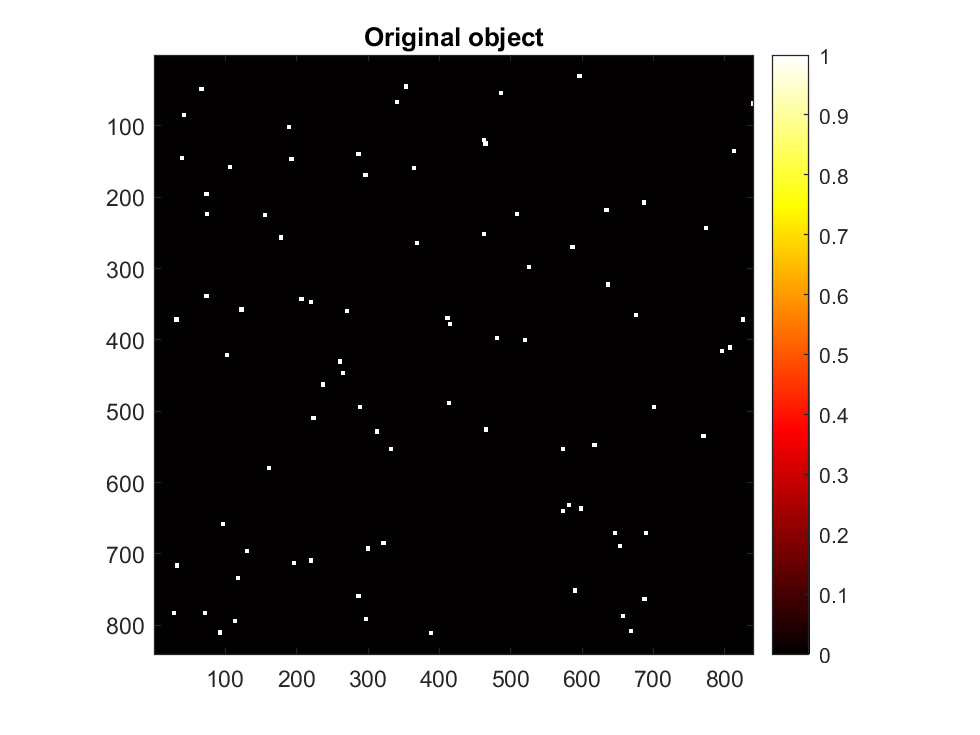

obj3d = randomScatter(obj.Nxy, obj.Nz, N_random, point_size, 0);   % Randomly distributed scatter object

if obj.Nz>1
    figure; show3d(obj3d, 0.01); title('Original object'); axis normal; caxis([0 1]);
else
    figure; imagesc(obj3d); title('Original object'); colormap(hot); colorbar; axis image;
end

Deal with the periodic problem of FFT in propagation with OTF

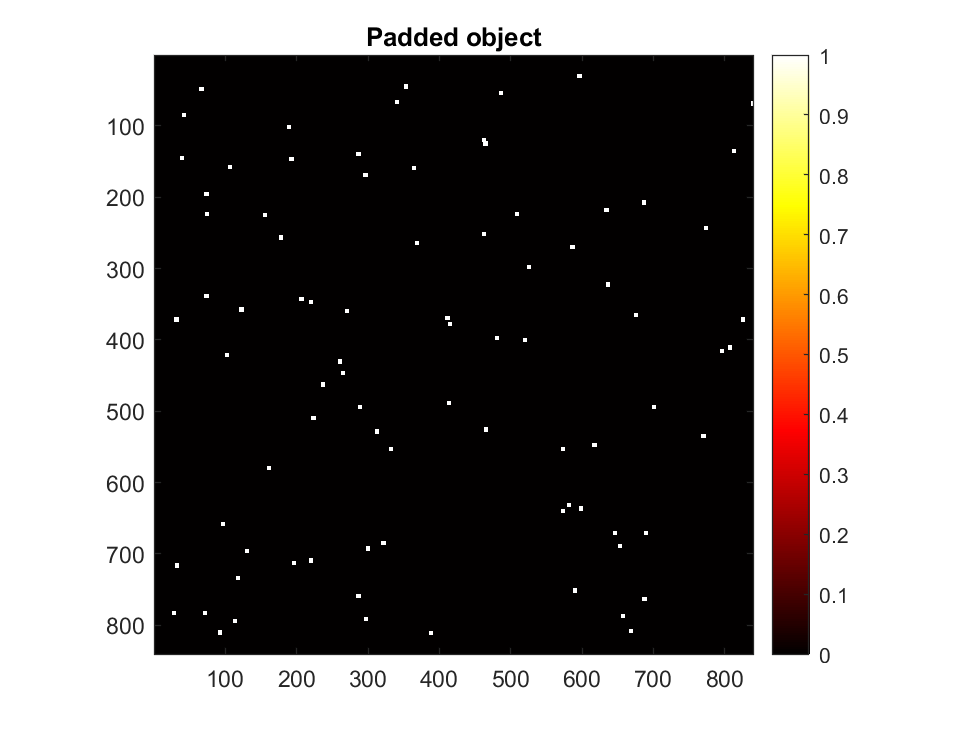

% get only center part of the object, and pad it with zeros
obj_view = obj3d(1+Nxy_bound:end-Nxy_bound, 1+Nxy_bound:end-Nxy_bound, :);
obj_view = padarray(obj_view, [Nxy_bound Nxy_bound]);

if obj.Nz>1
    figure; show3d(obj_view, 0.01); title('Padded object'); axis normal; caxis([0 1]);
else
    figure; imagesc(obj_view); title('Padded object'); colormap(hot); colorbar; axis image;
end

## Define the imaging process

Imaging Model:

* **Forward**: $ $y = {S}  {C}  {P} x $
 
$; 

* **Backward** (conjugate): $$x_p = P^T C^T S^T y$$ 

where: 

- $$P$$: wave propagator 

- $$C$$: hologram crop matrix, constrained by the objective lens 

- $$S$$: sampling operator by the objective lens 

- $$x$$: object 

- $$y$$: complex hologram

% generate propagation kernel of the imaging system
[otf, psf] = prop_kernel(obj.Nxy, obj.Nxy, sys.lambda, obj.ppo, z_range, sys.NA);    


temp = real(psf);
[M,I] = max(temp(:)); %I is the index maximun Here tu can change the function to max or min
[I_row, I_col] = ind2sub(size(temp), I) %I_row is the row index and I_col is the column index

I_row = 170

I_col = 21

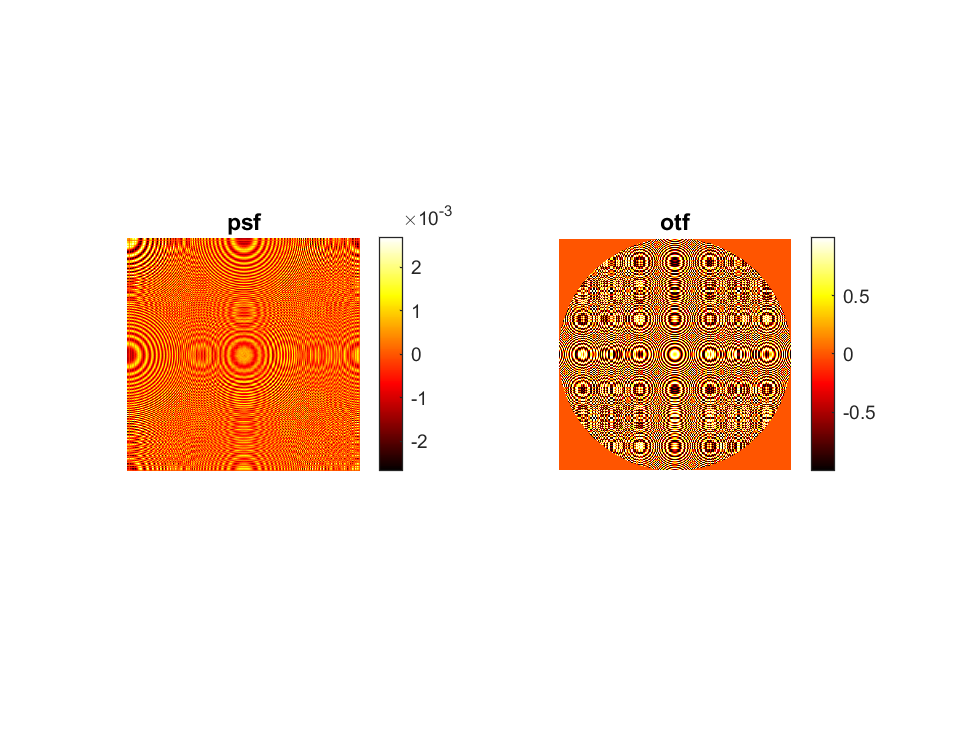



% show psf and otf
figure;
show_psfotf(psf, 121, 'psf', obj.Nz);
show_psfotf(otf, 122, 'otf', obj.Nz);

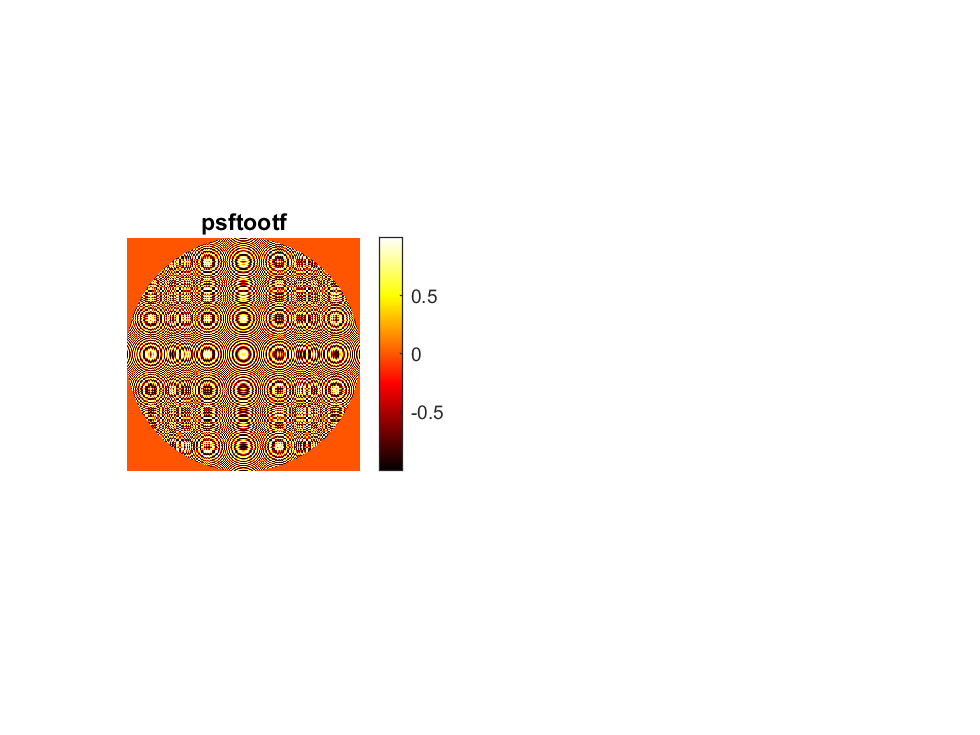



otf_new = fftshift(fft2(fftshift(psf)));
figure;
show_psfotf(otf_new, 121, 'psftootf', obj.Nz);

## define operators

Wave propagation in free-space through objective lens

% P  = @(x) FieldForwardProp(x, otf);    % forward 
% PT = @(y) FieldBackwardProp(y, otf);   % backward 

P  = @(x) FieldForwardPropPSF(x, psf);    % forward 
PT = @(y) FieldBackwardPropPSF(y, psf);   % backward 

% CCD crop. 
C  = @(x) x(1+sys.Ns_bound:end-sys.Ns_bound, 1+sys.Ns_bound:end-sys.Ns_bound, :);   % Crop the boundary
% CT = @(y) padarray(y, [sys.Ns_bound sys.Ns_bound]);                         % Pad the boundary with zero
CT = @(y) padarray(y, [sys.Ns_bound sys.Ns_bound], 0, 'both');                         % Pad the boundary with zero


% Sensor sampling.
% S  = @(x) imresize(x, [sys.Ns sys.Ns], 'Antialiasing', false);                            % Forward (obj.Nxy -> 
% ST = @(x) imresize(x, [obj.Nxy, obj.Nxy]);    % Backward
S  = @(x) imresize(x, [sys.Ns+2*sys.Ns_bound sys.Ns+2*sys.Ns_bound], 'Antialiasing', false);                            % Forward (obj.Nxy -> 
ST = @(x) imresize(x, [obj.Nxy, obj.Nxy]);    % Backward
% S  = @(x) imresize(x, [sys.Ns sys.Ns], 'Antialiasing', false);                            % Forward (obj.Nxy -> 
% ST = @(x) imresize(x, repmat(obj.Nxy - 2*sys.Ns_bound, [1 2]));    % Backward


% Padding object with zero, implement the out of scope effection
PO = @(x) padarray(x(1+Nxy_bound:end-Nxy_bound, 1+Nxy_bound:end-Nxy_bound, :), [Nxy_bound Nxy_bound]);

A  = @(x) C(S(P(x)));
AT = @(x) PT(ST(CT(x)));
% AT = @(x) PO(PT(ST(CT(x))));


% test operators
y = A(obj3d);

Unrecognized function or variable 'obj'.

x = AT(y);

% check Hermitian
% get_E = @(x) num2str(sum(abs(x(:)).^2));
% disp(['energy of obj: ' get_E(obj)])
% disp(['energy of y: ' get_E(y)])
% disp(['energy of x: ' get_E(x)])


## Hologram generation and reconstruction

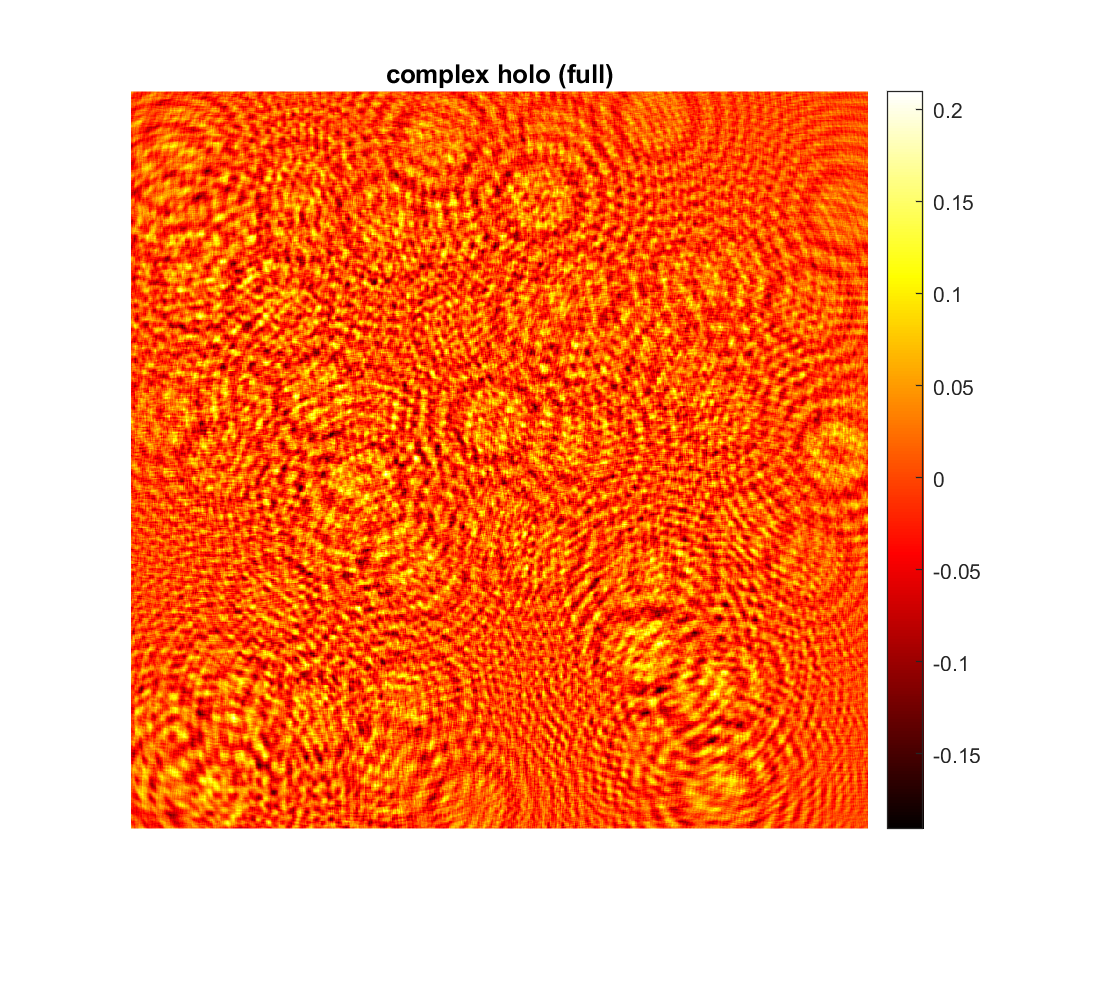

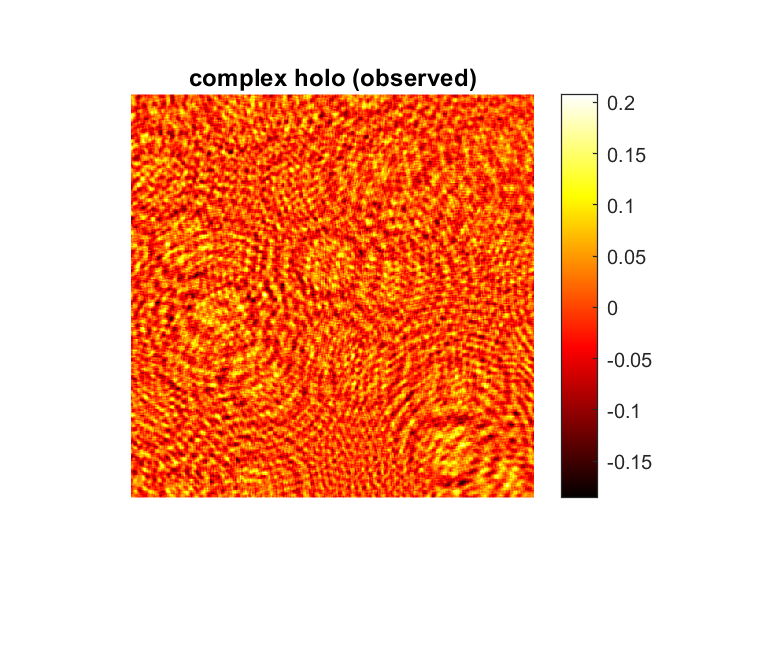

holo_field_full = P(obj3d);
holo_field = A(obj3d);

holo_full = holo_field_full + conj(holo_field_full) + abs(holo_field_full).^2;
holo = holo_field + conj(holo_field) + abs(holo_field).^2;
% holo = abs(holo_field).^2;

% show complex field
figure;  imshow(real(holo_field_full), []); title('complex holo (full)'); colormap(hot(256)); colorbar;
figure;  imshow(real(holo_field), []); title('complex holo (observed)'); colormap(hot(256)); colorbar;

% show gabor holograms
figure;  imshow((holo_full), []); title('Gabor holo (full)'); colormap(hot(256)); colorbar;

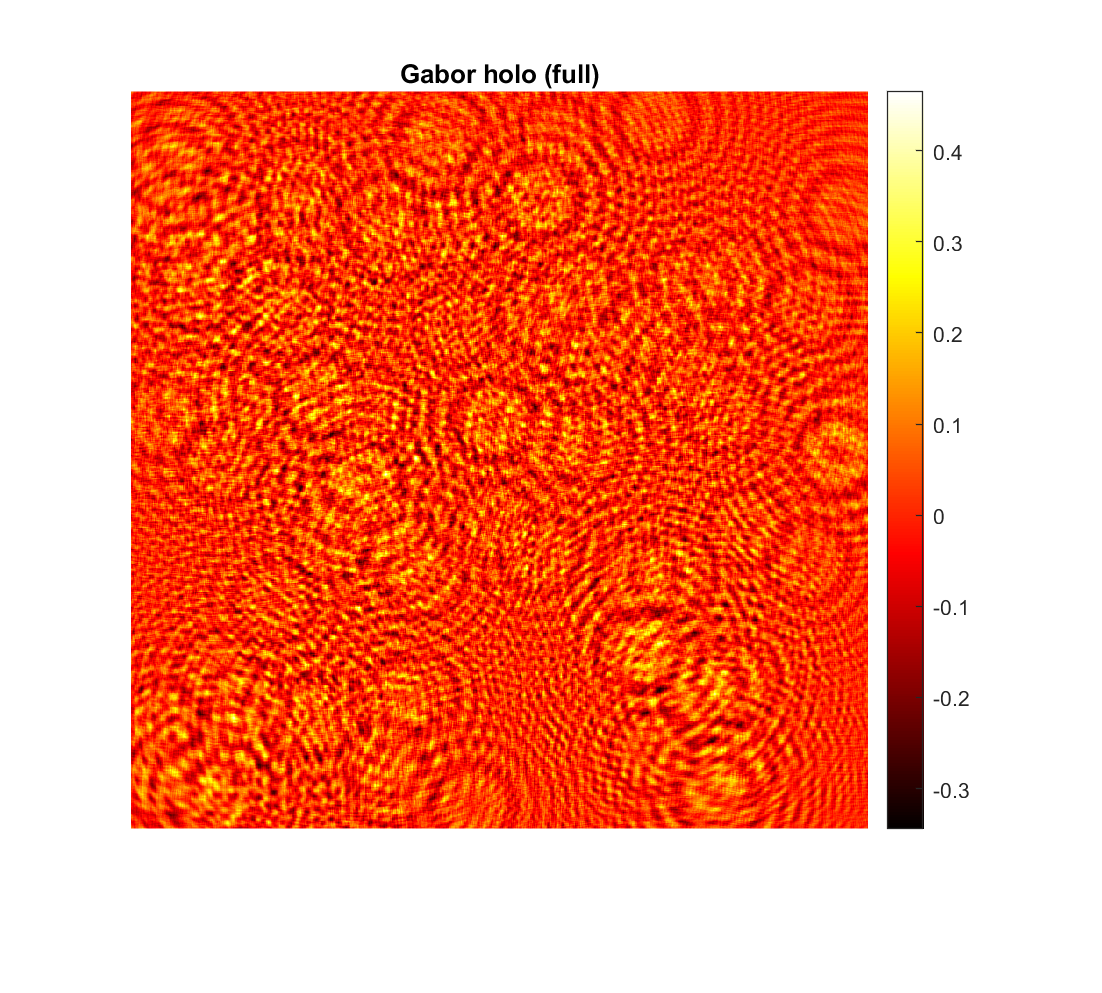

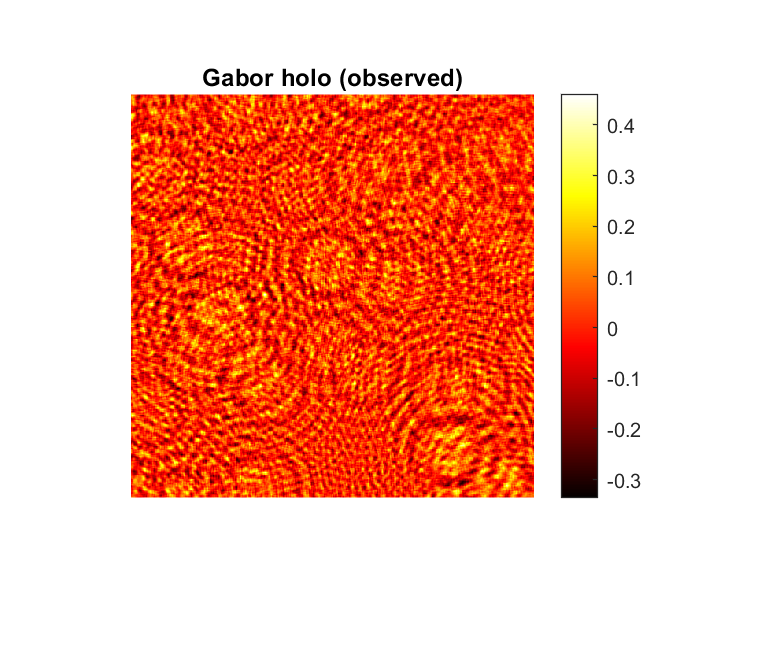

figure;  imshow((holo), []); title('Gabor holo (observed)'); colormap(hot(256)); colorbar;

## Reconstruction

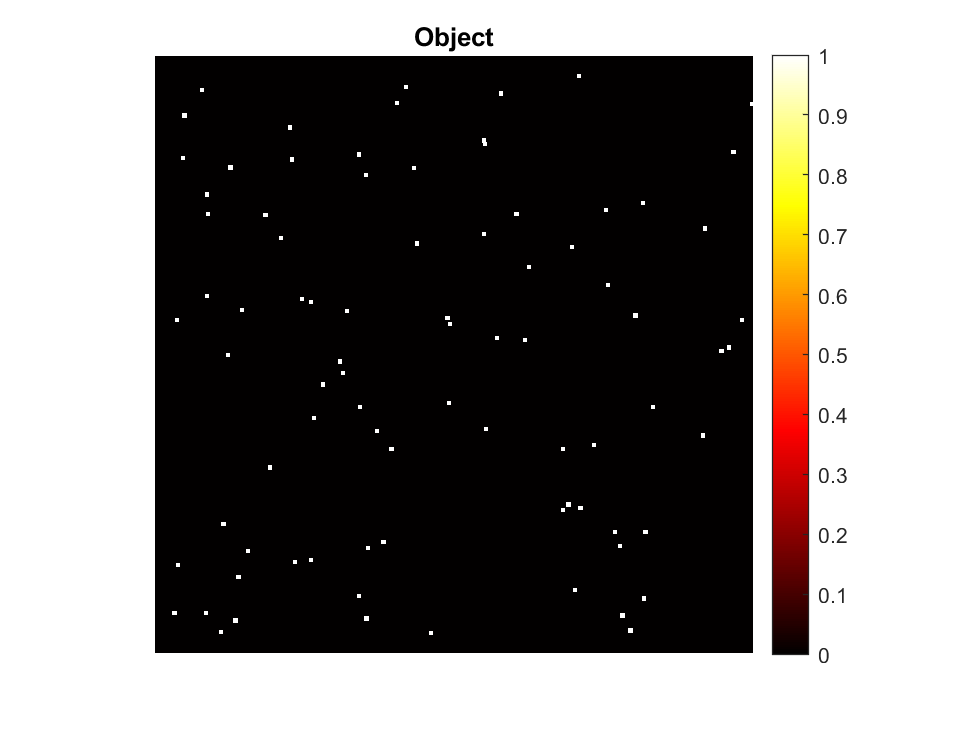

figure;

% Complex field and Gabor reconstructions (backward propagation)
re_obj_cpx = AT(holo_field);
re_obj_gabor = AT(holo);

% Display images
figure; imagesc(plotdatacube(obj3d)); title('Object'); colormap(hot); colorbar; axis image off; 

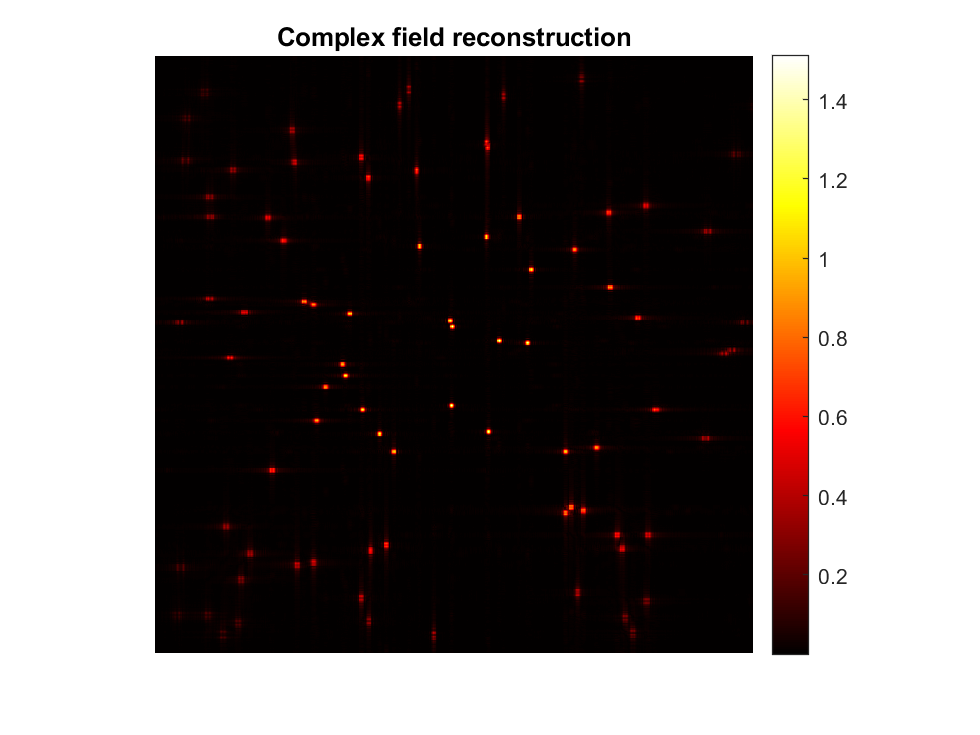

figure; imagesc(plotdatacube(abs(re_obj_cpx))); title('Complex field reconstruction'); colormap(hot); colorbar; axis image off;

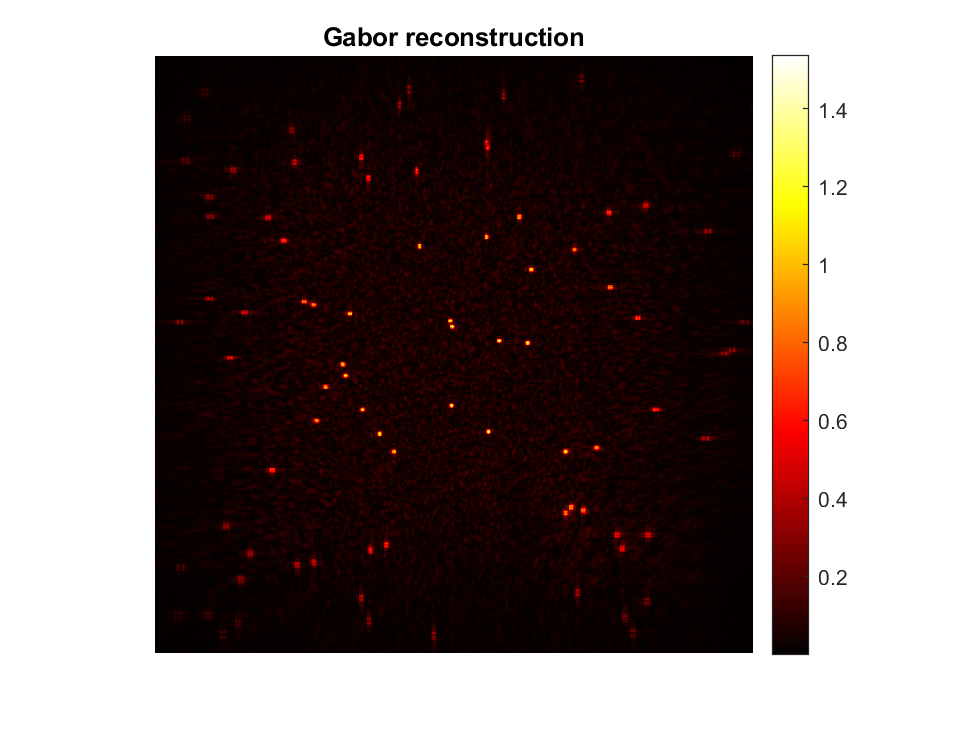

figure; imagesc(plotdatacube(abs(re_obj_gabor))); title('Gabor reconstruction'); colormap(hot); colorbar; axis image off;

Write images

% writedatacube(obj3d, [out_dir, 'object.png']);
% writedatacube(real(holo_field_full), [out_dir, 'holo_psf.png']);
% writedatacube(abs(re_obj_cpx), [out_dir, 're_obj_cpx_psf.png']);

% writedatacube(real(holo_field_full), [out_dir, 'holo_otf.png']);
% writedatacube(abs(re_obj_cpx), [out_dir, 're_obj_cpx_otf.png']);

% writedatacube(real(holo_field_full), [out_dir, 'holo_NA0.05.png']);
% writedatacube(abs(re_obj_cpx), [out_dir, 're_obj_cpx_NA0.05.png']);


% writedatacube(real(holo_field_full), [out_dir, 'holo_full.png']);
% writedatacube(real(holo_field), [out_dir, 'holo_crop.png']);
% writedatacube(abs(re_obj_cpx), [out_dir, 're_obj_crop.png']);

% % simple constraint optimization
iter = 20;
[re_obj_opt, loss_cpx] = admm_optim(A, AT, C, CT, holo_field, re_obj_cpx, iter);

iter = 1, loss = 3.914478e+01
iter = 2, loss = 3.915722e+01
iter = 3, loss = 3.916972e+01
iter = 4, loss = 3.918225e+01
iter = 5, loss = 3.919480e+01
iter = 6, loss = 3.920738e+01
iter = 7, loss = 3.921998e+01
iter = 8, loss = 3.923261e+01
iter = 9, loss = 3.924526e+01
iter = 10, loss = 3.925794e+01
iter = 11, loss = 3.927065e+01
iter = 12, loss = 3.928338e+01
iter = 13, loss = 3.929614e+01
iter = 14, loss = 3.930892e+01
iter = 15, loss = 3.932173e+01



[re_obj_opt_gabor, loss_gabor] = admm_optim(A, AT, C, CT, holo, re_obj_gabor, iter);


Display and write images


% figure; plot(log(loss_cpx));xlabel('Iteration'); ylabel('Loss'); title('Complex');
% figure; plot(loss_gabor); xlabel('Iteration'); ylabel('Loss'); title('Gabor');
% 
% % hologram
% % figure; imagesc(holo); title('hologram'); colormap(hot); colorbar; axis image;
% 
% % Display images
% figure; imagesc(plotdatacube(abs(re_obj_opt))); title('Optimization reconstruction from complex field'); colormap(hot); colorbar; axis image off;
% figure; imagesc(plotdatacube(abs(re_obj_opt_gabor))); title('Optimization reconstruction from Gabor hologram'); colormap(hot); colorbar; axis image off;
% 
% % writedatacube(real(holo_field_full), [out_dir, 'holo_full.png']);
% % writedatacube(real(holo_field), [out_dir, 'holo_crop.png']);
% % writedatacube(abs(re_obj_cpx), [out_dir, 're_obj_crop.png']);
% % writedatacube(abs(re_obj_gabor), [out_dir, 're_obj_crop_gabor.png']);
% % writedatacube(abs(re_obj_opt), [out_dir, 're_obj_crop_optim.png']);
% % writedatacube(abs(re_obj_opt_gabor), [out_dir, 're_obj_crop_gabor_optim.png']);